# **SIGNAL PROCESSING AND STATISTICS PROJECT **

**SET OF SENSORS AND JOINT ANALYSIS OF THE SIGNALS ACQUIRED BY IT WITH A KNOWN SIGNAL DOA **

Some of sensors are randomly placed in a 100 x 100 metre plot, to which a sinusoidal signal is transmitted.

The signal will reach the sensors with a delay depending on their position and the direction of the incident wave.

For simplicity, we assume the presence of a single source sufficiently far from the array to make the assumptions 

of far-field and plane wave.

**4 TESTS W: **

**1) TEST VARYING THE NUMBER OF SENSORS**

**2) TEST VARYING THE AMPLITUDE OF THE TRANSMITTED SIGNAL**

**3) TEST VARYING THE SNR **

**4) TEST VARYING THE FREQUENCY OF THE TRANSMITTED SIGNAL**

#### **1) TEST ON THE NUMBER OF SENSORS**

*By increasing the number of sensors, from 20 to 100 and finally to 180, the minimum peak becomes more and more pronounced, which denotes a strong dependency.*

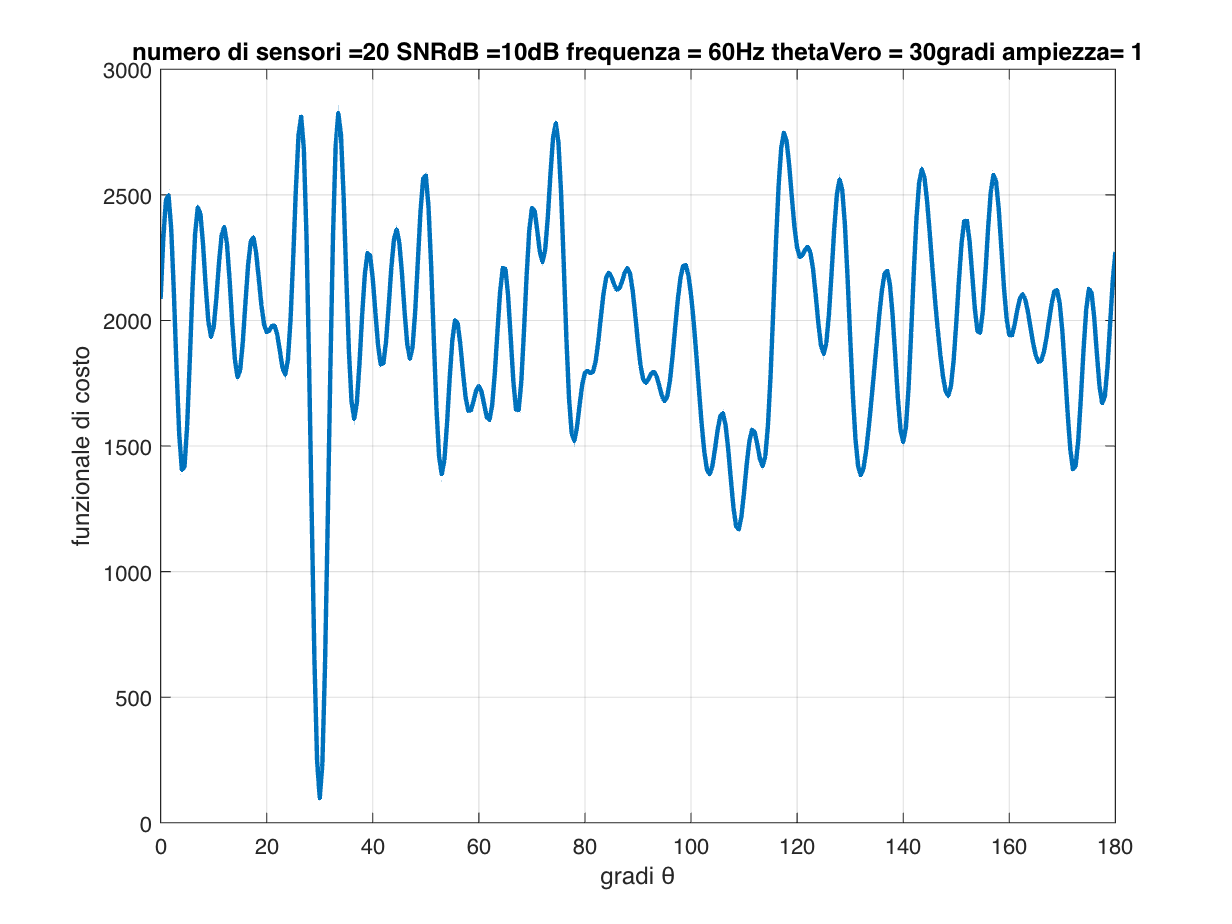

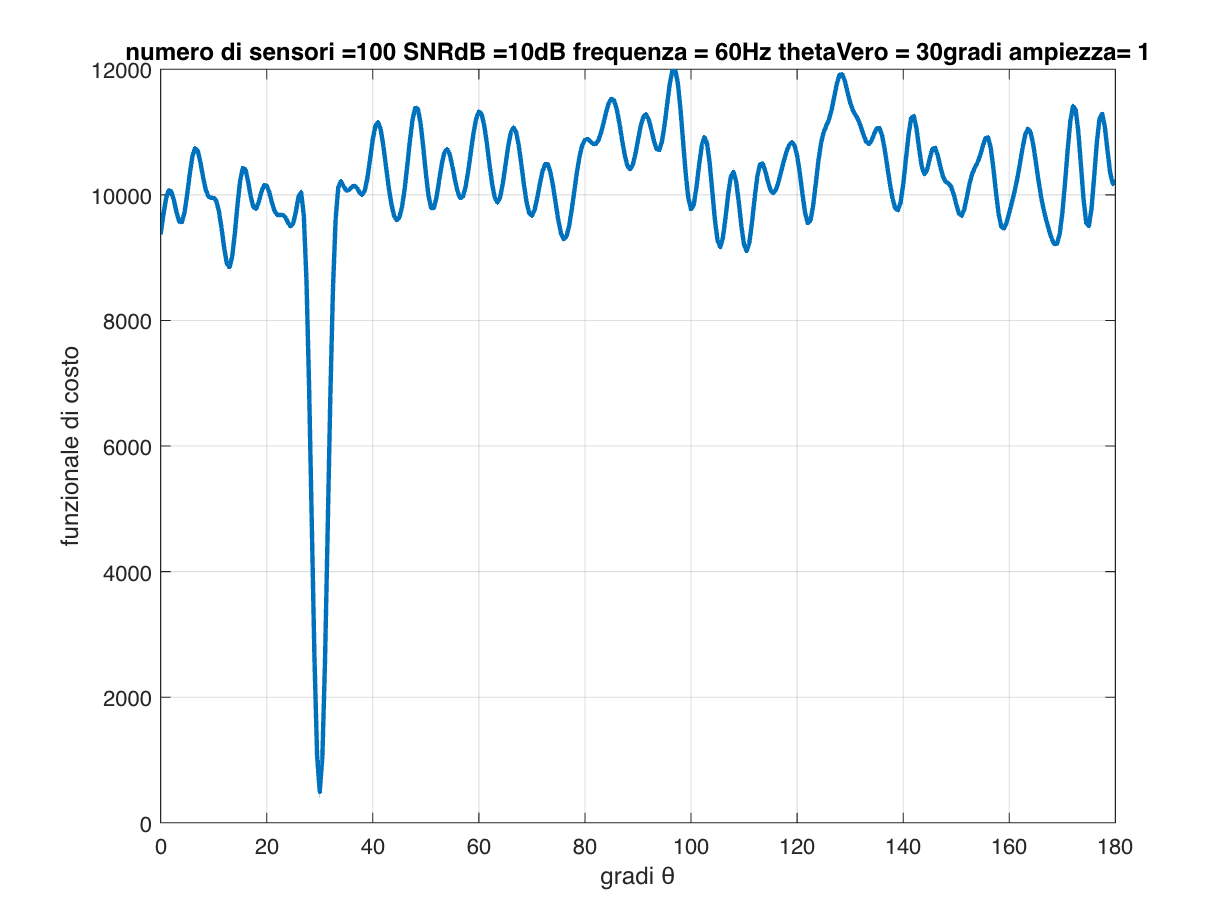

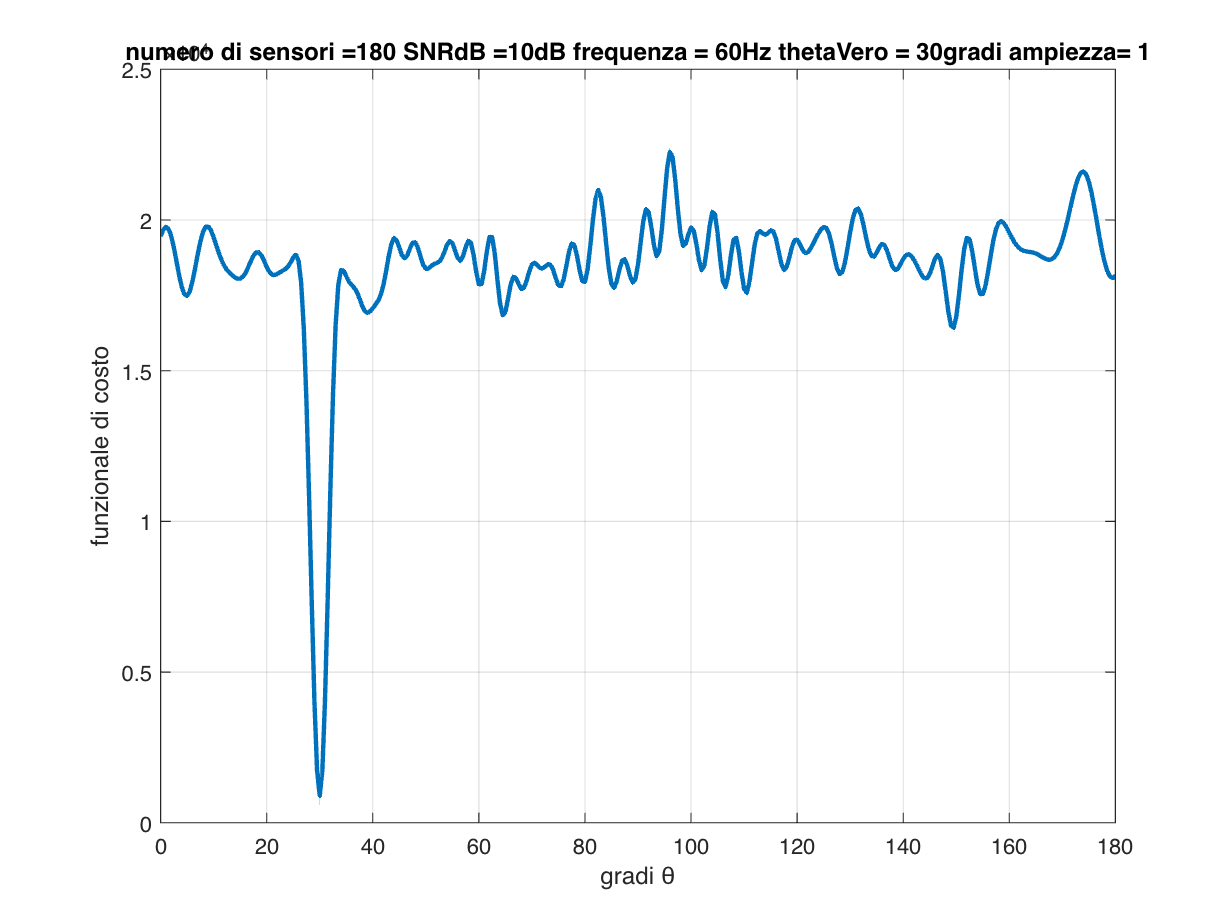

clc;
clear all;

SNR_dB = 10; %Rapporto segnale rumore in decibel
f = 60; %frequenza;
theta_vero = 30; 
a = 1; %ampiezza
sn = 20;

for sn = 20:80:180
    [theta_all, funzionale_di_costo] = DOA(sn, SNR_dB,f,theta_vero,a);
    graphicsTest(theta_all, funzionale_di_costo,sn,SNR_dB,f,theta_vero,a);
end

**2) TEST FOR VARYING THE AMPLITUDE OF THE TRANSMITTED SIGNAL**

*the amplitude took on 3 values: 1, 51 and 101. No substantial differences are found, the minimum peak does not stand out any more as the amplitude varies.*

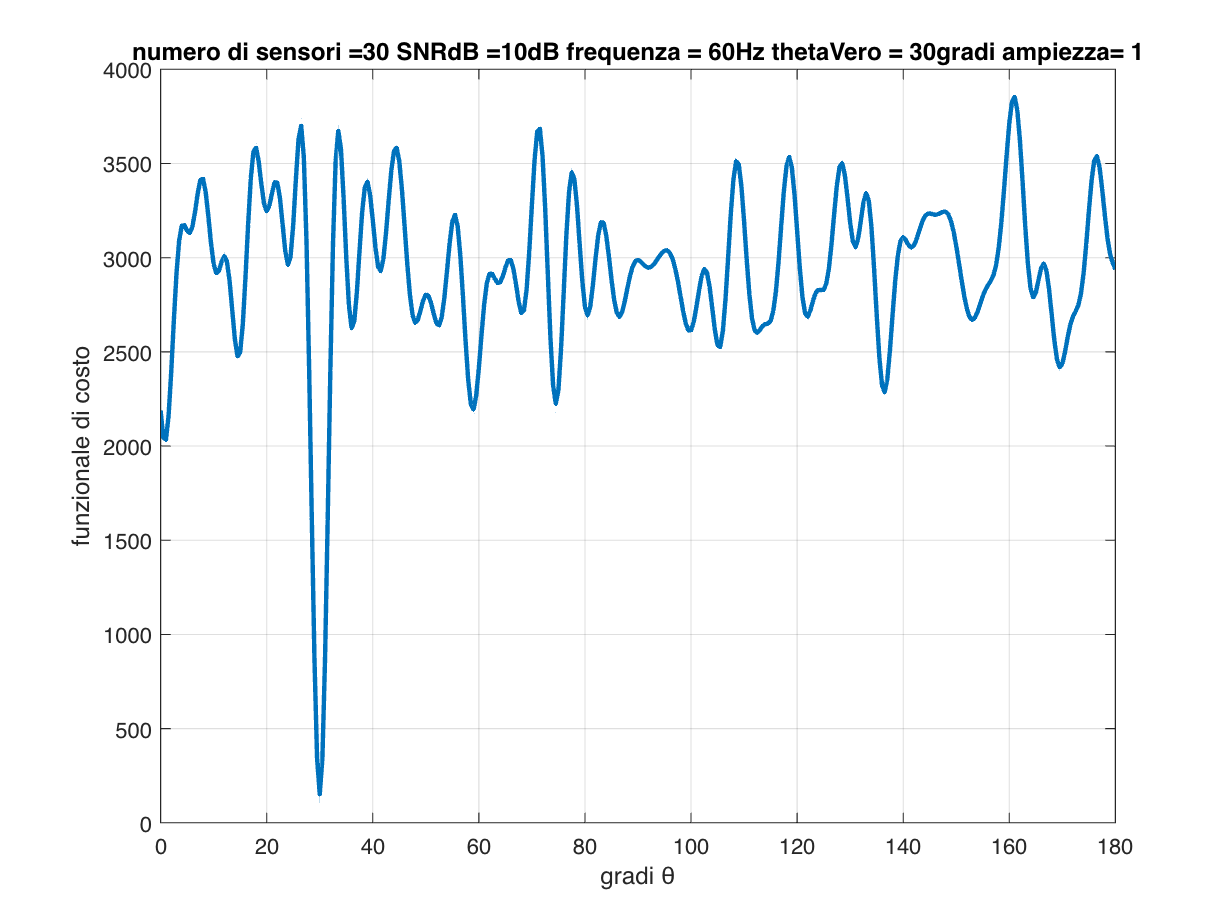

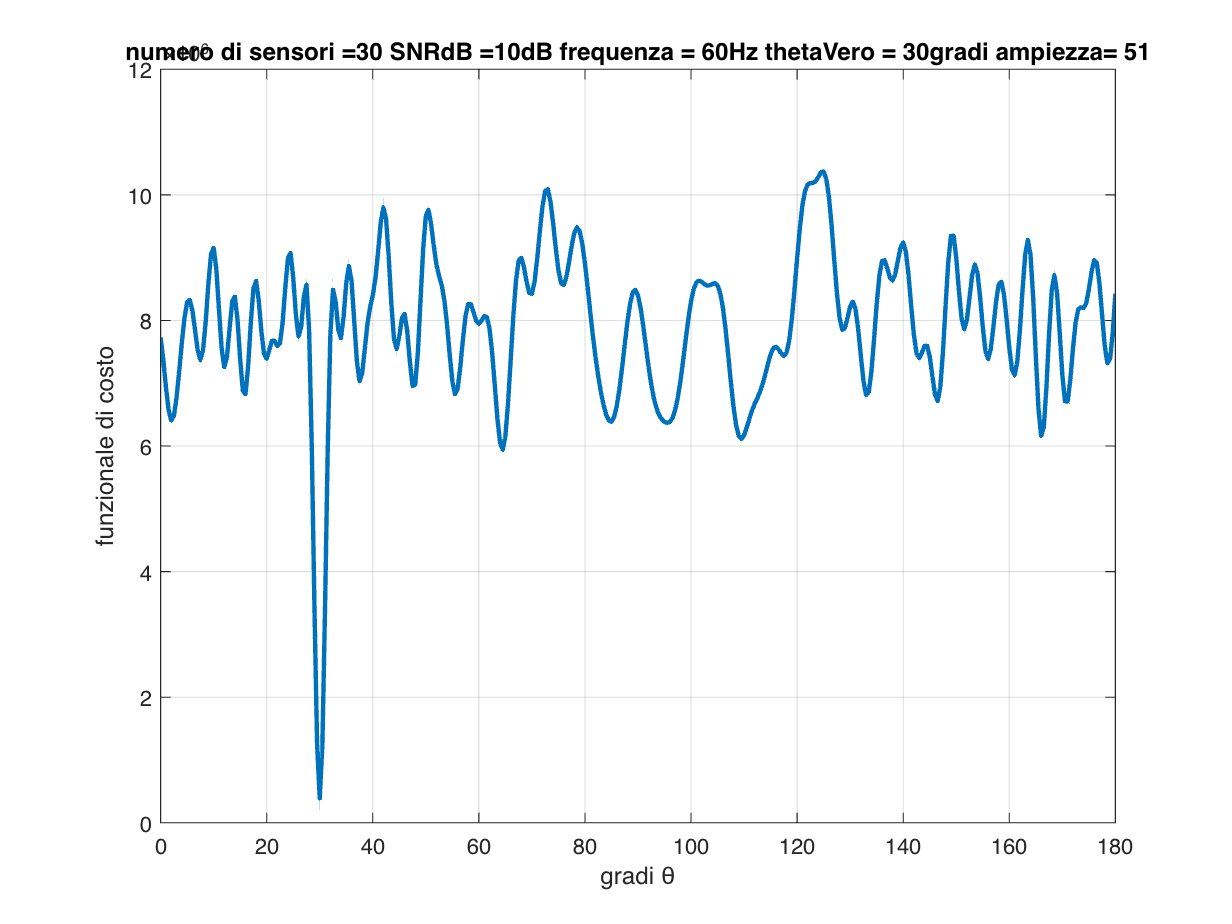

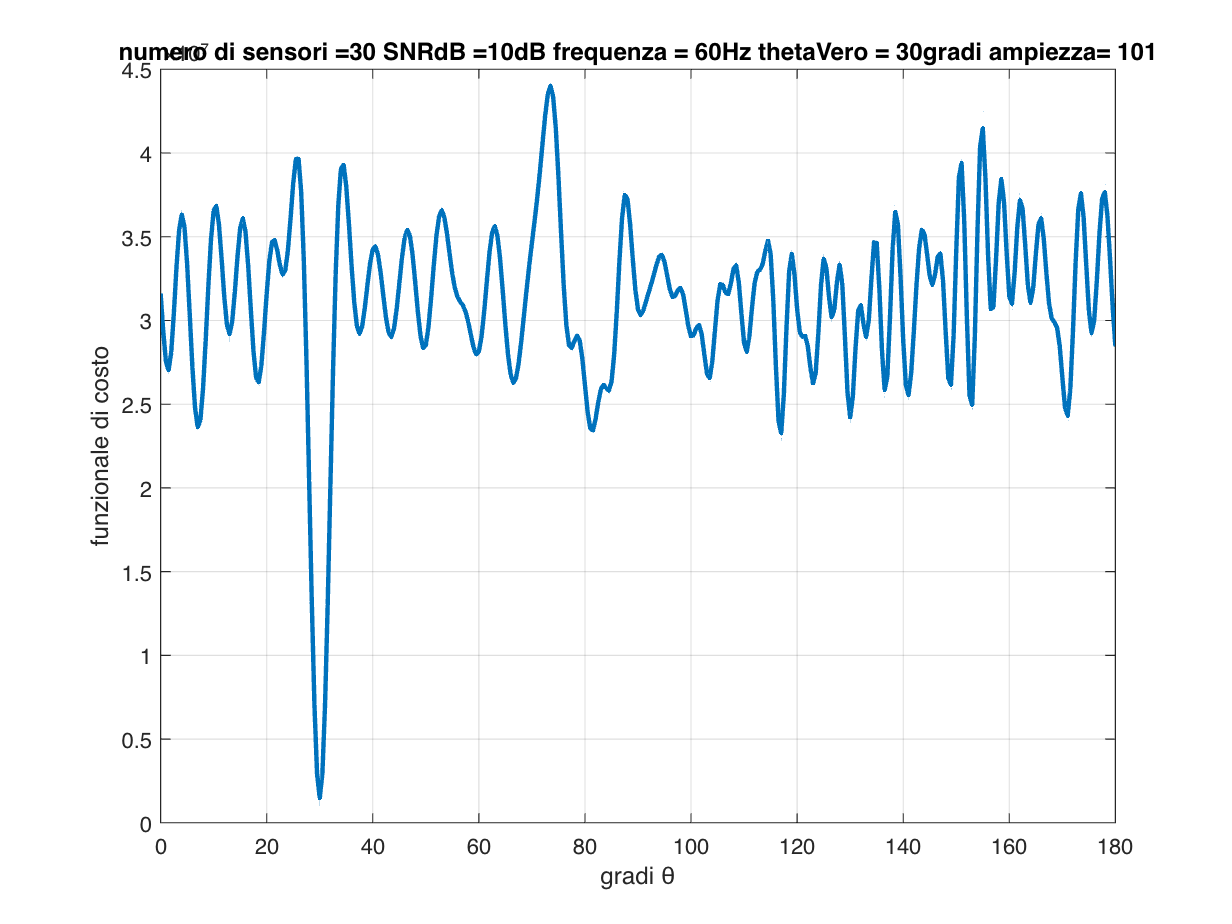

SNR_dB = 10; %Rapporto segnale rumore in decibel
f = 60; %frequenza;
theta_vero = 30; 
a = 1; %ampiezza
sn = 30;

for a = 1:50:101
    [theta_all, funzionale_di_costo] = DOA(sn, SNR_dB,f,theta_vero,a);
    graphicsTest(theta_all, funzionale_di_costo,sn,SNR_dB,f,theta_vero,a);
end

**3) TEST AT VARYING SNR **

*The SNR assumed 10, 30 and 50 dB respectively, again, the minimum peak is no more distinguishable as the signal-to-noise ratio varies.*

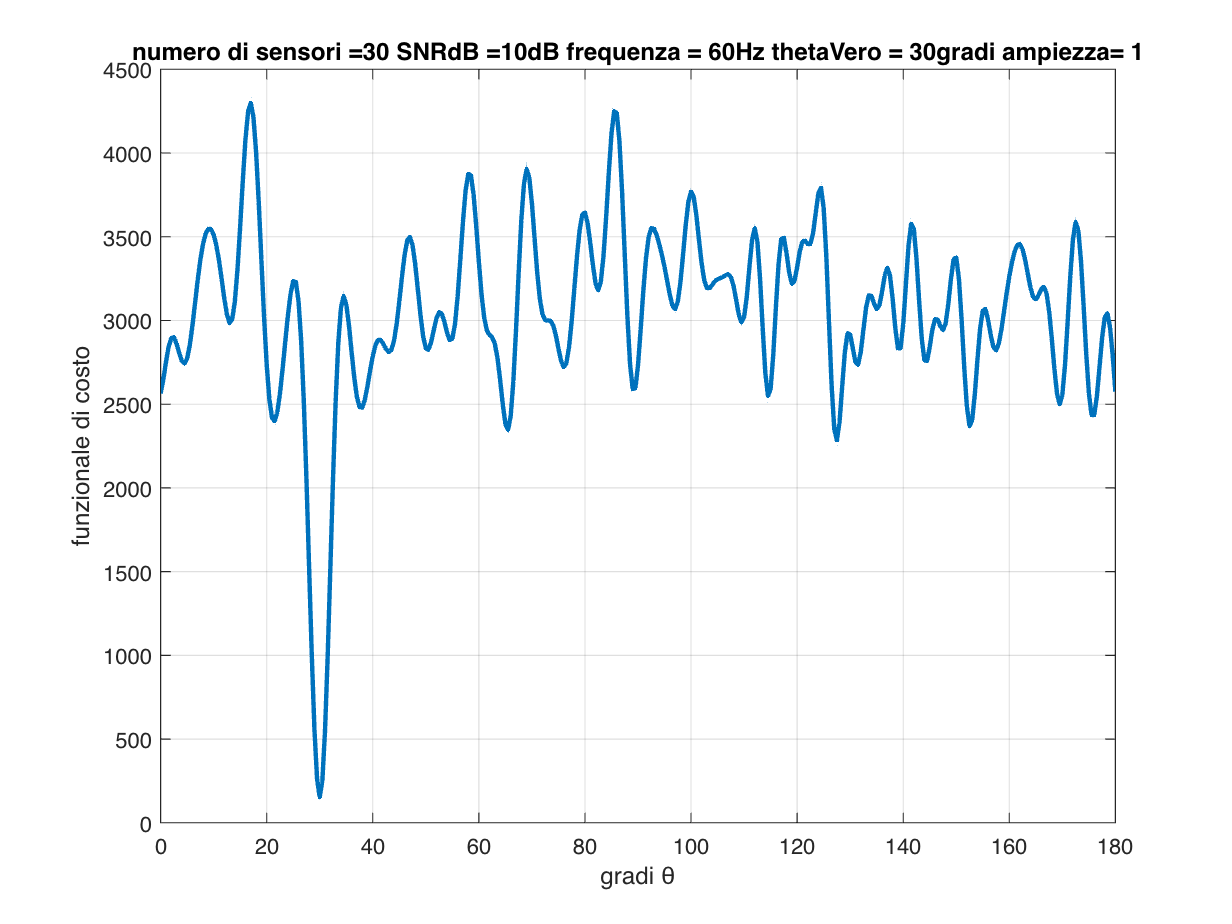

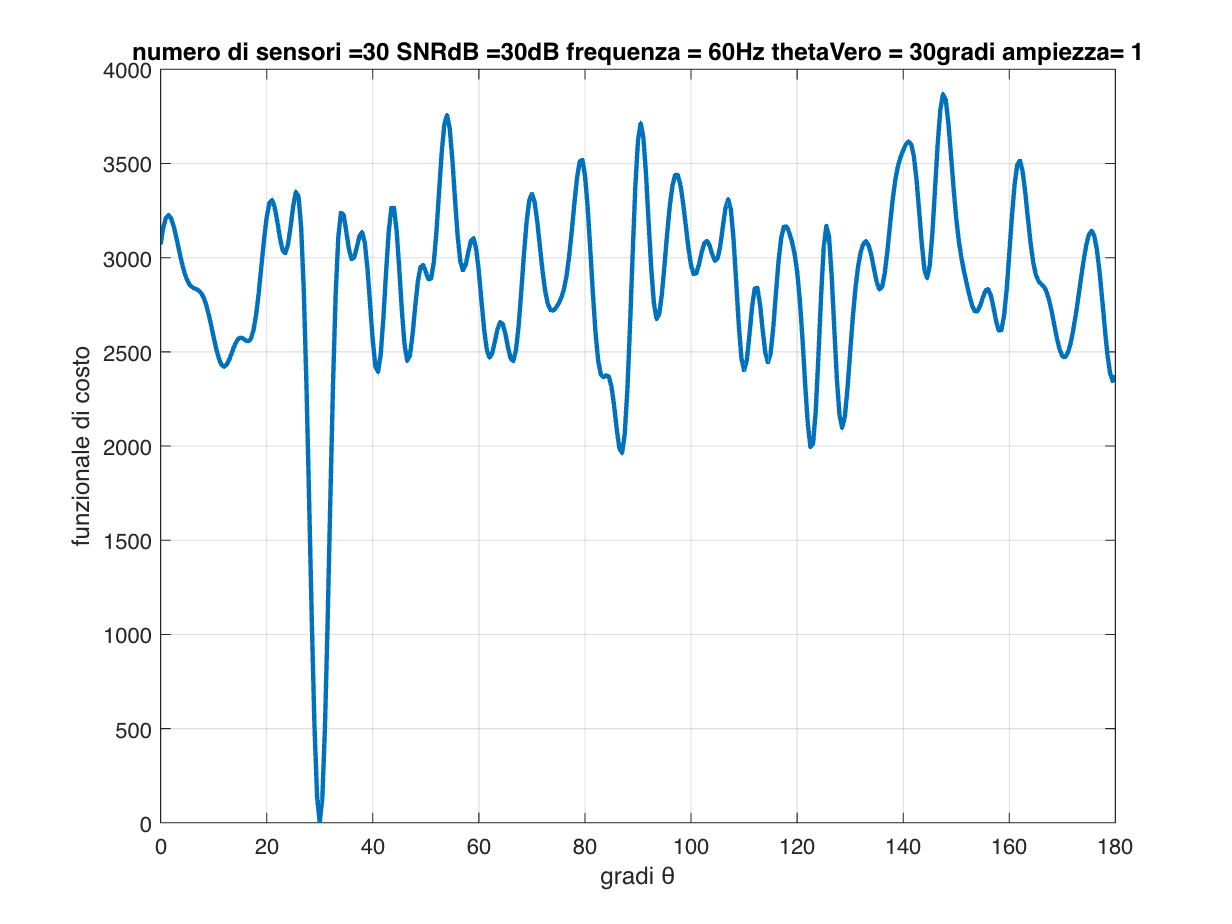

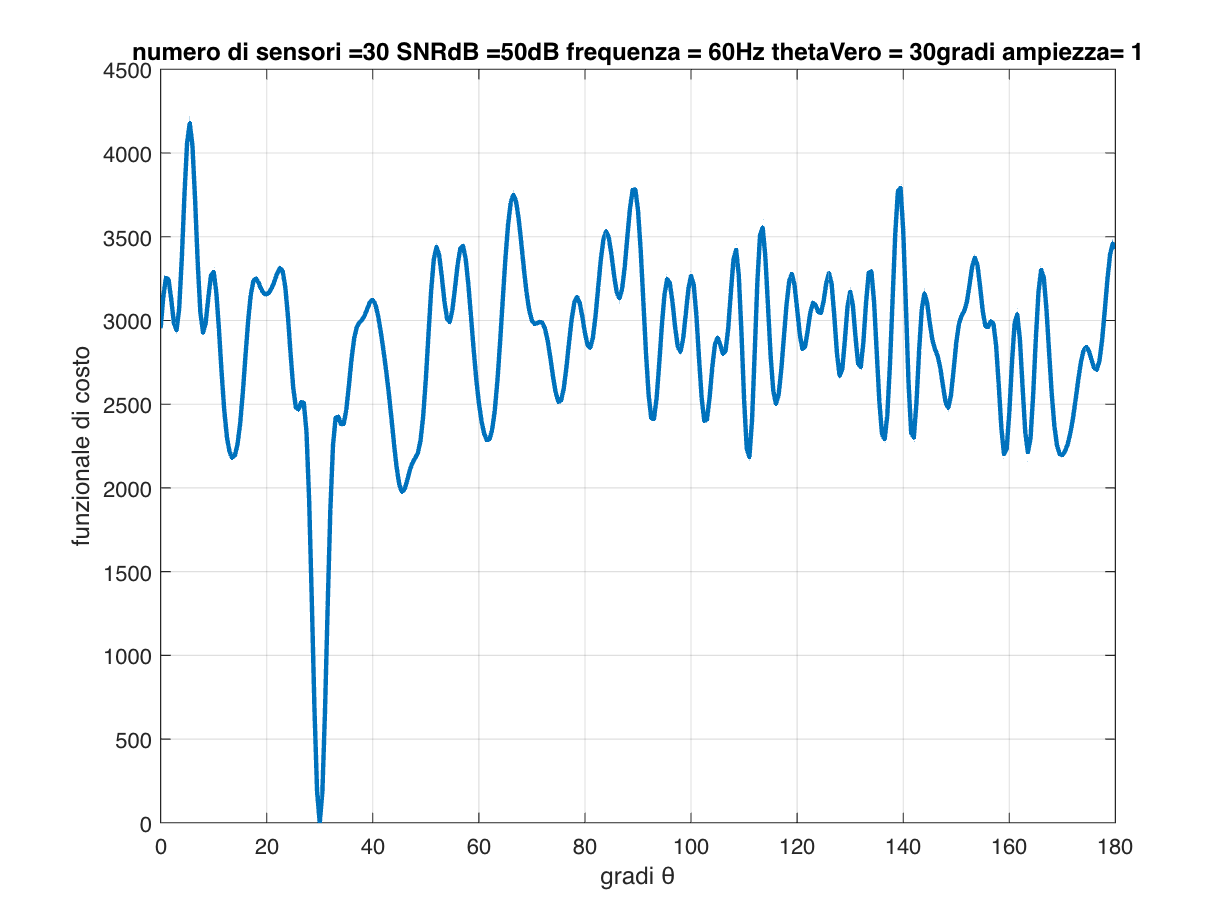

SNR_dB = 10; %Rapporto segnale rumore in decibel
f = 60; %frequenza;
theta_vero = 30; 
a = 1; %ampiezza
sn = 30;

for SNR_dB = 10:20:50
    [theta_all, funzionale_di_costo] = DOA(sn, SNR_dB,f,theta_vero,a);
    graphicsTest(theta_all, funzionale_di_costo,sn,SNR_dB,f,theta_vero,a)
end

**4) TEST AT VARYING THE FREQUENCY OF THE TRANSMITTED SIGNAL**

*the frequency took on 3 values: 30, 60 and 90 Hz. No substantial differences are found, the minimum peak does not stand out any more as the frequency of the transmitted sinus signal varies.*

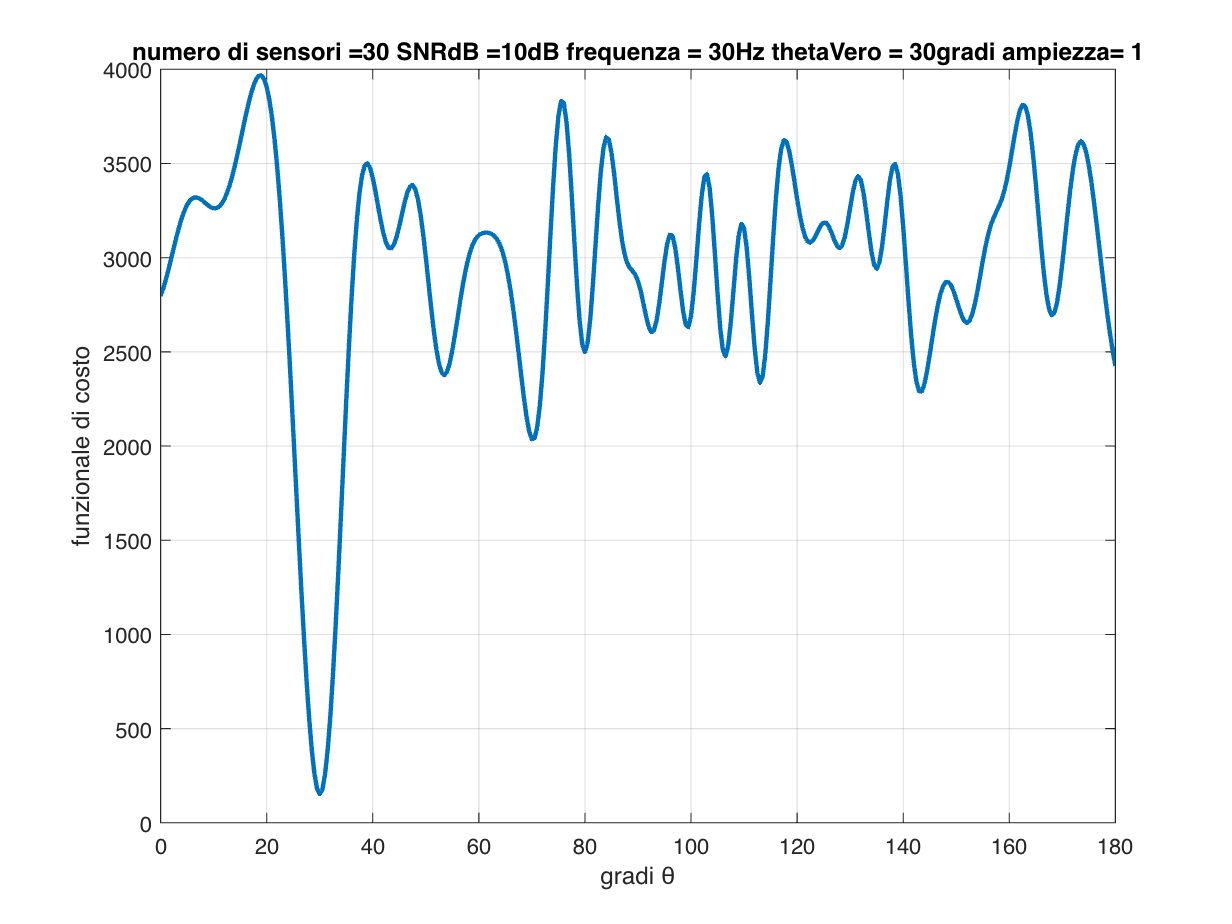

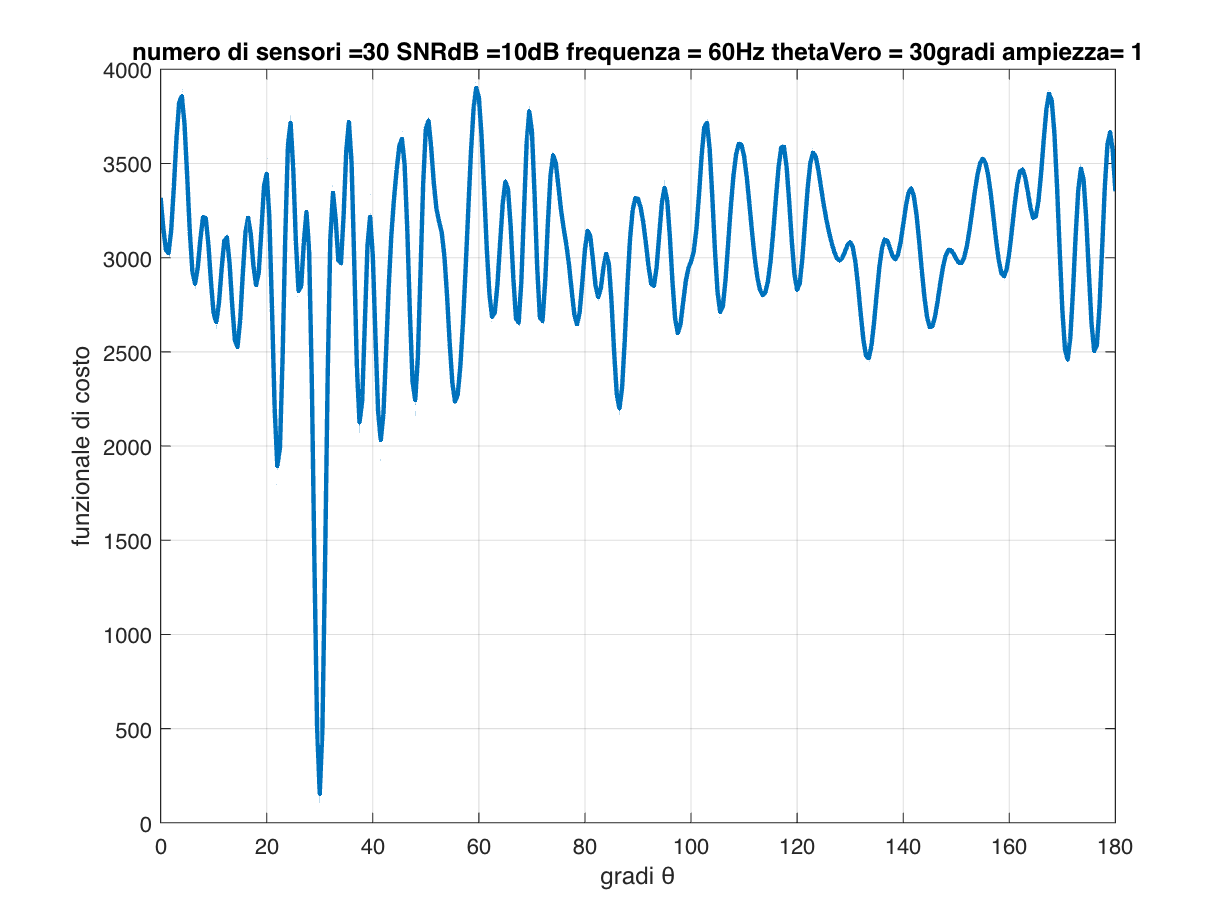

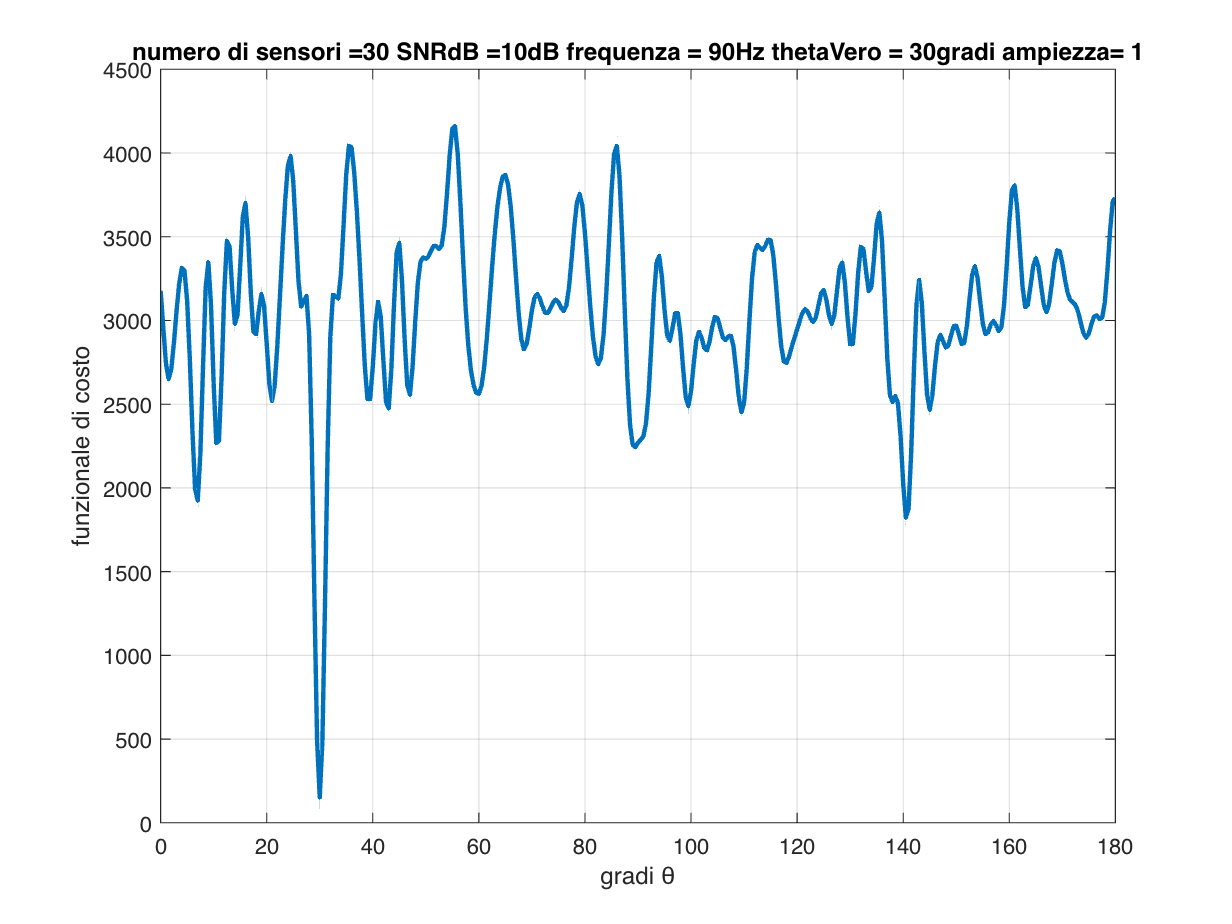

SNR_dB = 10; %Rapporto segnale rumore in decibel
f = 60; %frequenza;
theta_vero = 30; 
a = 1; %ampiezza
sn = 30;

for f = 30:30:90
    [theta_all, funzionale_di_costo] = DOA(sn, SNR_dB,f,theta_vero,a);
    graphicsTest(theta_all, funzionale_di_costo,sn,SNR_dB,f,theta_vero,a)
end

## **Function that plots the relationship between cost function and angle as the input data change**

function graphicsTest(theta_all, funzionale_di_costo,sn,SNR_dB,f,theta_vero,a)
    figure;
    plot(theta_all,funzionale_di_costo,"LineWidth",2);
    title(['numero di sensori ='  num2str(sn),...
        ' SNRdB =' num2str(SNR_dB),...
        'dB frequenza = ' num2str(f),...
        'Hz thetaVero = ' num2str(theta_vero),...
        'gradi ampiezza= ' num2str(a)]);
    
    ylabel('funzionale di costo')
    xlabel('gradi θ')
    grid on;
end


**Function that returns cost functionals and angles as the input data change**

function [theta_all,funzionale_di_costo] = DOA(sn,SNR_dB,f,theta_vero,a)

## **LET'S CONSIDER A SINUSOIDAL SIGNAL**

*Let us consider a sinusoidal signal of arbitrary frequency passed through the DOA function, *

*sampled at a sampling frequency of 1000 Hz *

*with N = 100 samples*

%crea un segnale sinusoidale 
%f = 60; %frequenza
fc = 1000;%frequenza di campionamento
Tc = 1/fc; %intervallo di campionamento
N = 100; %numero di campioni
phi = 0; %fase
%a = 100; %ampiezza
t = (0:N-1)*Tc;
s_tx_tot = a*sin(2*pi*f*t+phi);
tempo = length(t);


% plot(t,s_tx_tot)
% title('Segnale sinusoidale trasmesso')
% xlabel('time(s)')
% ylabel('amplitude(V)')
% grid on;

## **SENSORS RANDOMLY PLACED IN A 100X100 METRE PLOT**

l_x = 100;
l_y = 100;
x=rand([sn,1])*l_x; % x coordinate of a sn
y=rand([sn,1])*l_y; % y coordinate of a sn
A = [x y];

% figure;
% plot(x,y,'mo',...
%     'LineWidth',2,...
%     'MarkerEdgeColor','k',...
%     'MarkerFaceColor',[.17 0.66 .83],...
%     'MarkerSize',10)
% legend('SN')
% title('sensori presenti in uno spazio 100x100 metri');
% xlabel('metri')
% ylabel('metri')
% grid on

## **Signal model**

The signal pattern received by the sensor array is derived by making some simplifying assumptions.

We assume the presence of a single source sufficiently distant from the array to make the assumptions 

of far-field and **plane wave.**

It is possible to detect the direction of arrival (**DOA**) of the signal, from one or more sources, with respect to the receiving array.

## 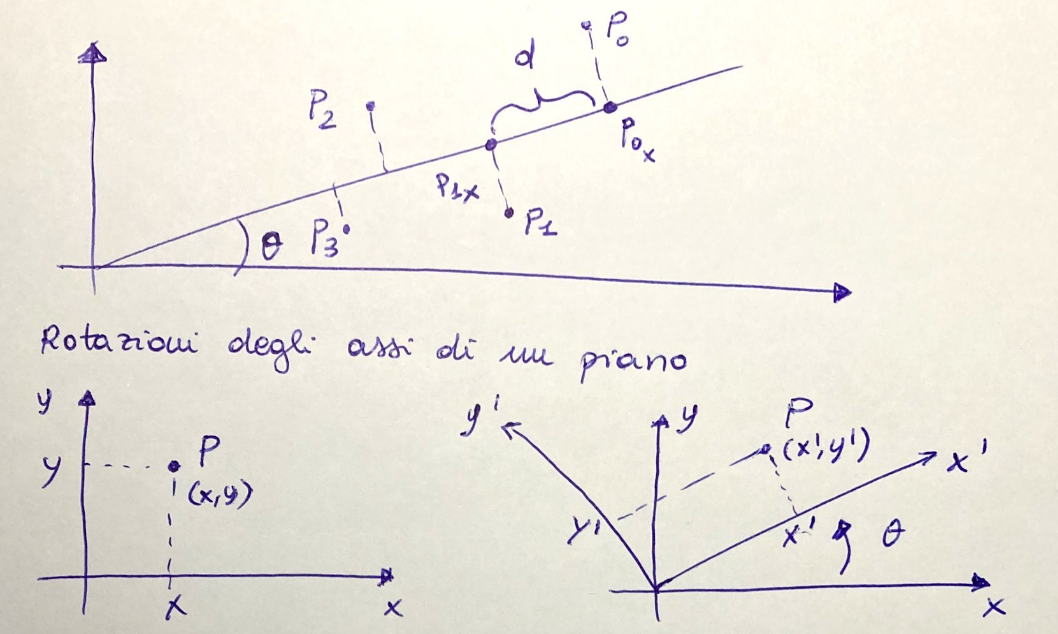

## Given any of the following points 

## 
$$\begin{array}{l}
P_0 =\left(x_0 ,y_0 \right)\\
P_1 =\left(x_1 ,y_1 \right)
\end{array}$$


## I can rotate the axes of a plane by an angle

## 
$$\begin{array}{l}
x^{\prime } =\textrm{xcos}\left(\theta \right)+\textrm{ysen}\left(\theta \right)\\
y^{\prime } =\textrm{ycos}\left(\theta \right)-\textrm{xsen}\left(\theta \right)
\end{array}$$


## and calculate the distance d as the difference of the x components rotated by an angle $\theta$

## $d={P^{\prime } }_{0x} -{P^{\prime } }_{1x}$      (1)

## Let's express the x components following the formula for axis rotation

## 
$$\begin{array}{l}
{P^{\prime } }_{0x} =x_o \cos \left(\theta \right)+y_0 \textrm{sen}\left(\theta \right)\\
{P^{\prime } }_{1x} =x_1 \cos \left(\theta \right)+y_1 \textrm{sen}\left(\theta \right)
\end{array}$$


## substituting in (1)

## 
$$d=\left(x_0 -x_1 \right)\cos \left(\theta \right)+\left(y_0 -y_1 \right)\textrm{sen}\left(\theta \right)$$


## we can simplify this formula by renaming

## 
$$d_x =x_0 -x_1$$


## 
$$d_y =y_0 -y_1$$


## 
$$d=d_x \cos \left(\theta \right)+d_y \textrm{sen}\left(\theta \right)$$


## I can define the signal delay at the k-th sensor with respect to the reference sensor 

## $\tau_k =\frac{d}{c_{\textrm{vel}} }=\frac{\;d_x \cos \left(\theta \right)+d_y \textrm{sen}\left(\theta \right)}{c_{\textrm{vel}} }$          (2)

## Signal model in the presence of a delay minus a multiplicative constant, we have 

## $y_k \left(t\right)=s\left(t\right)e^{-{\textrm{jw}}_c \tau_k } +e_k \left(t\right)$     (3)

## I replace (2) in (3) and get

## 
$$y_k \left(t\right)=s\left(t\right)e^{-{\textrm{jw}}_c \frac{\;d_x \cos \left(\theta \right)+d_y \textrm{sen}\left(\theta \right)}{c_{\textrm{vel}} }} +e_k \left(t\right)$$


## where

## 
$$\begin{array}{l}
d_x =x_0 -x_k \;\\
d_y =y_0 -y_k 
\end{array}$$


## with $x_{0\;}$and $y_0$ components of the reference sensor

## The signals acquired from all sensors can be expressed in the following vector form

## $\left\lbrack \begin{array}{c}
y_1 \left(t\right)\\
y_2 \left(t\right)\\
\ldotp \\
\ldotp \\
y_m \left(t\right)
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{c}
1\\
e^{-{\textrm{jw}}_c \frac{\;d_{x_1 } \cos \left(\theta \right)+{d_y }_1 \textrm{sen}\left(\theta \right)}{c_{\textrm{vel}} }} \\
\ldotp \\
\ldotp \\
e^{-{\textrm{jw}}_c \frac{\;{d_x }_{m-1} \cos \left(\theta \right)+{d_y }_{m-1} \textrm{sen}\left(\theta \right)}{c_{\textrm{vel}} }} 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
s\left(t\right)
\end{array}\right\rbrack$ + $\left\lbrack \begin{array}{c}
e_1 \left(t\right)\\
\ldotp \\
\ldotp \\
\ldotp \\
e_m \left(t\right)
\end{array}\right\rbrack$

## we can indicate the steering vector with a($\theta$)

## 
$$y\left(t\right)=a\left(\theta \right)s\left(t\right)+e\left(t\right)$$


## Case where $\theta$ is the true one

%costanti fissate 
c_vel = 340; %m/s speed of sound in air fissata
w_c = 2*pi*f; %fissata pulsazione normalizzata

SNR = 10^(SNR_dB/10);
sigma2 = a^2/(2*SNR);

%conversione dei gradi in radianti
theta_rad = deg2rad(theta_vero) ; %fissato a 30 gradi, converto l'angolo in radianti 
s_trasm = zeros(length(t),sn);

for k = 1:length(t)
    
        time = t(k);
        
        d_x  = A(:,1)-A(1,1);
        d_y  = A(:,2)-A(1,2);
                       
        tau  = (d_x*cos(theta_rad)+ d_y*sin(theta_rad))/c_vel; %ritardo segnale
        sv = exp(-1j*w_c*tau);%steering vector
        
        s_trasm(k,:) = sv*a*sin(2*pi*f*time+phi);           
end

errore = 1/sqrt(2)*(randn(length(t),sn) + 1i*randn(length(t),sn))*sqrt(sigma2); % moltiplico 1/sqrt(2) perchè è un segnale complesso 
x_oss = s_trasm + errore ;

## I VARIATE THE ANGLE BETWEEN  $0\le \theta \le 180$ degrees

y_k = zeros(length(t),sn);
passo = 0.5; 
theta_all = 0:passo:180;

for j = 1: length(theta_all)
    
    theta = theta_all(j);
    theta_rad = deg2rad(theta); %converto l'angolo in radianti 
    
    for k = 1:length(t)
        
        time = t(k);
        
        d_x  = A(:,1)-A(1,1);
        d_y  = A(:,2)-A(1,2);
                       
        tau  = (d_x*cos(theta_rad)+ d_y*sin(theta_rad))/c_vel; %ritardo segnale
        sv = exp(-1j*w_c*tau);%steering vector
            
        s_trasm = a*sin(2*pi*f*time+phi);
        y_k(k,:) = sv*s_trasm;
        
    end
    errore = y_k - x_oss;
    funzionale_di_costo(j) = (norm(errore,'fro'))^2;
end
end

                                                                                                                                               **                ALESSANDRO MAGGI **